zv = [0;0;0];
ex = [1;0;0];
ey = [0;1;0];
ez = [0;0;1];

h_fig = diagrams.setup;

p = [0;1.5;0]

p =          0
    1.5000
         0


theta = wrapTo2Pi(subproblem1(p-ex,ex,  ez)*2);

*** Warning *** ||p|| and ||q|| must be the same!!!


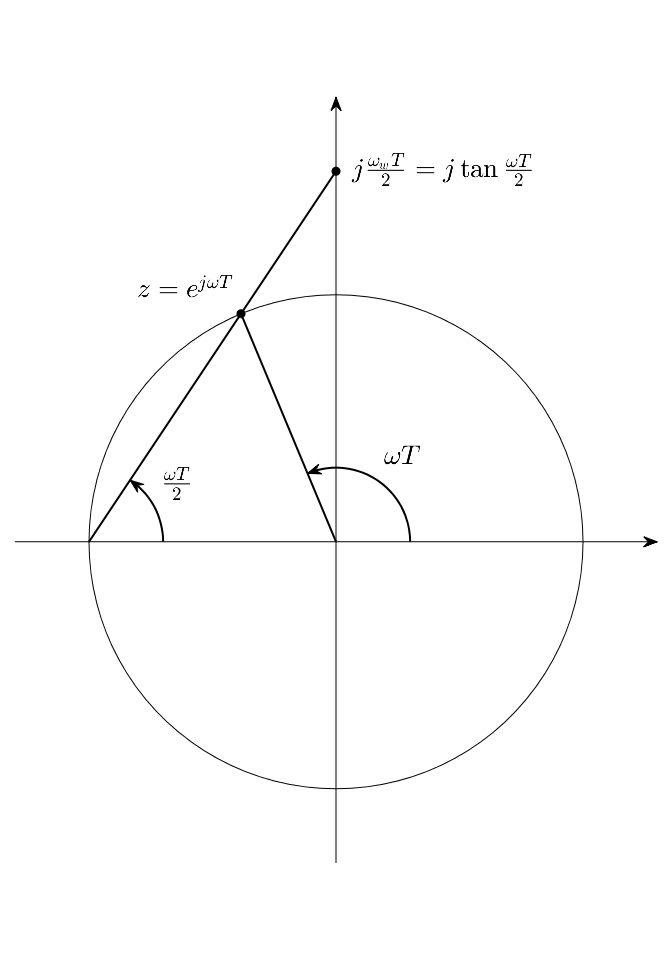

p_int = rot(ez, theta)*ex;

view(2)
hold on

C = diagrams.gen_circle([0;0;1], [1;0;0]);
plot3(C(1,:), C(2,:), C(3,:), 'k');

diagrams.line(-ex, p);
diagrams.line(zv, p_int);

diagrams.angle_arc(ex*0.3, ez, zv, theta);
diagrams.angle_arc(-ex+ex*0.3, ez, -ex, theta/2);

diagrams.dot(p);
diagrams.dot(p_int);

AXIS_SIZE = 1.3;
diagrams.arrow(-AXIS_SIZE*ex, AXIS_SIZE*ex);
diagrams.arrow(-AXIS_SIZE*ey, 1.8*ey);

diagrams.text(p, "$j \frac{\omega_w T}{2} = j \tan \frac{\omega T}{2}$", ...
    VerticalAlignment="middle", Margin=12);
diagrams.text(p_int, "$z = e^{j \omega T}$", ...
    VerticalAlignment = "bottom", HorizontalAlignment="right");
diagrams.text(rot(ez, theta/2)*ex*0.3, "$\omega T$", ...
    VerticalAlignment = "bottom", HorizontalAlignment="left");
diagrams.text(-ex+rot(ez, theta/4)*ex*0.3, "$\frac{\omega T}2$", ...
    VerticalAlignment = "bottom", HorizontalAlignment="left");

hold off
diagrams.redraw()

diagrams.save(h_fig, "example_diagram_2d", "./")